# Unsupervised Learning Problem Set

[⇦ Main Menu](matlab:open('../../MainMenu.mlx'))

Apply unsupervised learning to analyze a cancer dataset. 

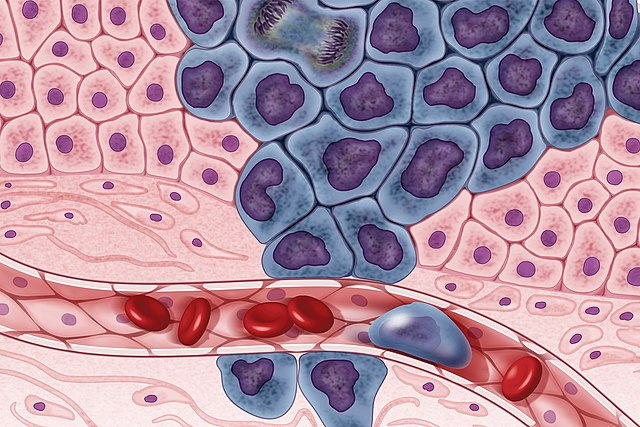

**Before you get started:**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections, and they will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Unsupervised Learning: Discovering Hidden Patterns in Cancer Biopsies

Imagine being handed hundreds of tissue samples, in which some are cancerous, others are not, but you don't know which ones are which. All you have are measurements, including the thickness of the cell clumps, the uniformity of the cells, their stickiness, and more. Could you, just by analyzing these patterns, use unsupervised learning to begin to separate the healthy from the harmful? The cancer cells are a different shape and size from the cells in the healthy tissue, so this kind of information can help us diagnose cancer given a biopsy of such tissue. Your goal is to uncover natural groupings, or clusters, in the data that might correspond to cancerous and non-cancerous tissue.

An [illustration](https://commons.wikimedia.org/wiki/File:Cancer_cells_illustration_(40379829875).jpg) of cancer cells (blue) encroaching on normal tissue (pink). 

### Data Preparation

  **Activity.** Load the dataset and learn about the dataset.

To begin, we load and examine the dataset by reviewing its structure, contents, and dimensions. This step helps us understand what each patient sample represents and the amount of information contained within it. By familiarizing ourselves with the data early on, we set the stage for applying unsupervised learning techniques that can help us distinguish between patients with and without ovarian cancer.

#### Tasks. 

- Load the `cancer_dataset.mat` into the workspace into the variables `cancerInputs` and `cancerTargets`  using the [**load**](https://www.mathworks.com/help/matlab/ref/load.html?s_tid=srchtitle_site_search_1_load) command.

- Learn more about `cancer_dataset.mat` from the MATLAB Documentation using the [**doc**](https://www.mathworks.com/help/releases/R2025a/matlab/ref/doc.html?searchHighlight=doc&s_tid=doc_srchtitle) command.

% Enter code for Tasks 1 and 2 below.


load cancer_dataset.mat cancerInputs cancerTargets
whos -file cancer_dataset
doc cancer_dataset

 **Reflect**. How many attributes are in this dataset? How many biopsies?

### Transpose Data for Better Trend Visualization

We will start exploring the `cancerInputs` dataset. Starting with the original dataset, where each row in the `cancerInputs` variable represents one of the eight cell attribute levels and each column corresponds to a biopsy, we see that the data structure does not align well with intuitive graphical representations. 

We want the "Biopsies" to be the rows and the cell attributes to be the columns.

  **Activity.  **Restructure Data to convert rows to columns. 

#### **Task **

- Restructure variables by using the [**transform**](https://www.mathworks.com/help/releases/R2025a/matlab/ref/matlab.io.datastore.transform.html?searchHighlight=transform&s_tid=doc_srchtitle) command on `cancerInputs` and `cancerTargets. `Store the results in `cancerInputs` and `cancerTargets.`

% Enter code for Task 1 below

cancerInputs = transpose(cancerInputs);
cancerTargets = transpose(cancerTargets);

## Perform PCA of the Dataset

Use the [Live Task](https://www.mathworks.com/help/releases/R2025a/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html), [Reduce Dimensionality](https://www.mathworks.com/help/releases/R2025a/stats/reducedimensionalitytask.html?searchHighlight=reduce+dimensionality&s_tid=doc_srchtitle) to perform PCA on the dataset.

#### Task

- On the **Live Editor** tab, select **Task** > **Reduce Dimensionality**; or on the **Insert** tab, select **Task** > **Reduce Dimensionality **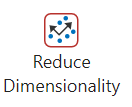.

-  Select `cancerInputs` as the Input data.

-  Specify dimensionality reduction criterion to 95%.

-  Deselect 2D biplot to show only the Scree plot of explained variances and the 2D scatter plot. Then press the  button.

% Principal Component Analysis
[coeffs, transformedData, ~, ~, explained] = pca(cancerInputs);

% Compute number of components from explained variance
enoughExplained = cumsum(explained)/sum(explained) >= 95/100;
numberOfComponentsToKeep = find(enoughExplained, 1);
disp("The number of components needed to explain at least 95% of the variance is "+ num2str(numberOfComponentsToKeep))

% Display results
figure
colorMap = colormap("lines");
barPlot = bar(explained);
hold on;
plot(cumsum(explained),"*-","Color",colorMap(3,:));
hold off;
barPlot(1).FaceColor = "flat";
barPlot(1).CData(1:numberOfComponentsToKeep,:) = repmat( ...
    colorMap(2,:),[numberOfComponentsToKeep 1]);
label = ["Selected components"; sprintf("Cumulative explained\nvariance")];
legend(label,"Location","best");
title("Scree Plot of Explained Variances")
xlabel("Principal component")
ylabel("Variance explained (%)")
clear barPlot colorMap label explained

figure
scatter(transformedData(:,1),transformedData(:,2), "Marker", ".");
title("Scatter Plot of Principal Components")
xlabel("Component 1")
ylabel("Component 2")
clear coeffs enoughExplained explained
transformedData = transformedData(:,1:numberOfComponentsToKeep);
clear numberOfComponentsToKeep

 **Reflect**. What if anything, do you lose if you include all of the attributes in your analysis? What if anything, do you gain or lose by only including one component? 

### Perform K-Means Clustering on the PCA-Reduced Data

Let's apply unsupervised learning to uncover natural groupings in our cancer cell dataset using **k-means clustering**. This method assigns each observation to one of $k$ groups based on similarity.

The first step is choosing the number of clusters, $k$. While there are mathematical techniques to estimate the optimal value, it's common to experiment with different values or use domain knowledge  how the data is expected to be grouped.

Use the [Live Task](https://www.mathworks.com/help/releases/R2025a/matlab/matlab_prog/add-live-editor-tasks-to-a-live-script.html), [Cluster Data](https://www.mathworks.com/help/stats/clusterdatatask.html) to perform k-means clustering on the PCA-reduced data.

  **Activity. **Perform k-means clustering on PCA-Reduced Data

#### Tasks

- On the **Live Editor** tab, select **Task** > **Cluster Data **.

- In the task, select the **k-Means Clustering** algorithm.

- Select the `transformedData` variable as the input data. Note, if you have run this script multiple times, ensure that the `transformedData `variable is the same as the one in the previous section. It may be` transformedData2 `or` transformedData3.`

- Set the number of clusters to `2`, if necessary.

- In the **Live Editor** tab, click the  **Run** button to run the task.

- Go to the  menu on the top right of the task and select Convert to Code.

 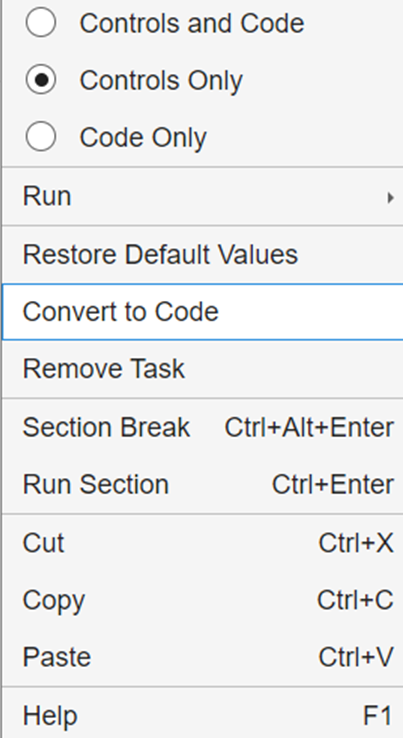


% Perform k-means clustering using specified number of clusters (K value)
K = 2;
[clusterIndices,centroids] = kmeans(transformedData,K);
clear K

% Display results



% Display 2D scatter plot (PCA)
figure
[~,score] = pca(transformedData);
clusterMeans = grpstats(score,clusterIndices,"mean");
h = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h)
    h(i).DisplayName = strcat("Cluster",h(i).DisplayName);
end
clear h i score
hold on
h = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h.DisplayName = "ClusterMeans";
clear h clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");
 

### Compare Clusters to Cancer Diagnoses

To evaluate the performance of our clustering, we need a quantitative method to compare the cluster assignments with the known diagnostic labels. A **confusion matrix** provides a structured way to do this by comparing predicted cluster labels with actual class labels. You can view an [example confusion matrix](matlab:open('./UnsupervisedLearning.mlx')) in [Unsupervised Learning](matlab:open('./UnsupervisedLearning.mlx')). To enhance interpretability, we will visualize the **confusion matrix** as a **heatmap**, where color intensity reflects the frequency of each prediction. If the clustering is meaningful, we expect to see most values concentrated along the diagonal or in specific corners of the heatmap. 

**Compare the results of applying k-means clustering **to our **PCA-reduced dataset and our full dataset.** we aim to assess how well the resulting clusters align with the known cancer diagnoses. Specifically, we will compare the cluster assignments to the cancer status of each patient, as indicated in the `cancerTargets` dataset, where a diagnosis of 0 is benign, and of 1 is malignant.

  **Activity. ** Display the confusion matrix to compare clusters to cancer diagnoses.

#### Task

- Convert the second column of `cancerTargets` to a `categorical` variable named `diagnosis.`

- Enter this code to correct the size of the confusion chart.

You can create a confusion matrix between the variables `results` and `output` as follows: 

        3. Create a `confusionchart `in the variable `cm `using` diagnosis `and` clusters `from the PCA code above`.`

        4. Use dot notation to complete the `Title, XLabel, YLabel, RowDisplayLabels, `and` ColumnDisplayLabels.`

% Convert the second column of cancerTargets to a categorical variable
diagnosis = categorical(cancerTargets(:,2)); 

% Convert cluster indices to categorical
% clusters = categorical(idx);
clusters = categorical(clusterIndices(:) - 1);



% Create a confusion matrix using confusionchart
cm = confusionchart(clusters,diagnosis);
cm.Title = "Confusion Chart";
cm.XLabel = "Predicted Class";
cm.YLabel = "True Class";
cm.RowDisplayLabels = ["Benign","Malignant"];
cm.ColumnDisplayLabels = ["True","False"];

### Calculate the Accuracy of the Predictions

The accuracy of our predictions can be determined by the following equation:


$$\text{Accuracy} = \frac{\text{True Positives +True Negatives}}{\text{True Positives + False Positives + True Negatives + False Negatives$$


  **Activity. ** Compute the accuracy of your predictions using the results from the confusion matrix. 

PerCentTruePosNNeg = ((447+222)/(447+222+11+19))*100;
disp("The accuracy of our clustering is " + num2str(round(PerCentTruePosNNeg)) + "%.");

 **Reflect**. If you limit the number of principal components included in the analysis,  does the confusion chart give similar results?

## Further Exploration

You can explore further into clustering algorithms for machine learning in [Machine Learning Methods: Clustering](https://www.mathworks.com/matlabcentral/fileexchange/135381-machine-learning-methods-clustering).

[⇦ Return to the main menu](matlab:open('../../MainMenu.mlx'))

## Local Helper Functions

If you wish to create local helper functions, you can write them below. 